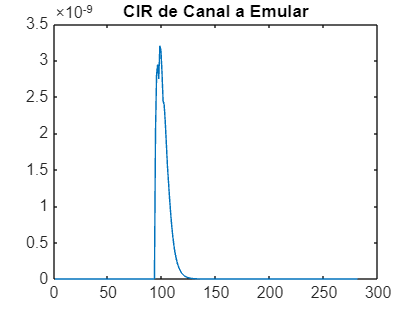

%% intro
clear all
rng(2,"twister")

run("main_channel.m")

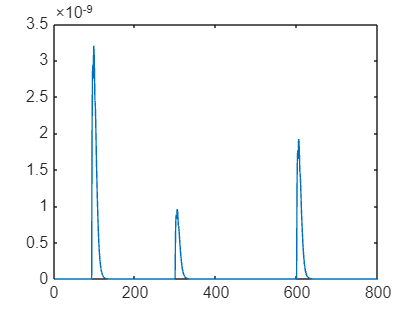


newresponse = zeros(1,800);
newresponse(1:281) = Final_response(1:281);
newresponse(300:451) = Final_response(94:245)*0.3;
newresponse(600:751) = Final_response(94:245)*0.6;

figure
plot(newresponse)

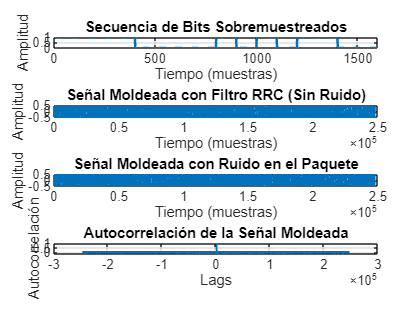


% Parámetros del filtro
rolloff = 0.25; % Factor de roll-off (0 a 1)
span = 6;       % Número de símbolos que abarca el filtro
samplesPerBit = 10; % Muestras por bit

% Crear el filtro RRC
rcFilter = rcosdesign(rolloff, span, samplesPerBit, 'sqrt');
filtLen  = length(rcFilter); 
filtDelay= (filtLen - 1)/2;  % Group delay in samples

% Generar el flujo de bits
preamble = [1,1,1,1,0,0,0,0,1,0,1,0,1,1,0,0]; % Ejemplo de preámbulo
packet = round(rand(1, 24717)); % Paquete de 100 bits aleatorios

bits = [preamble, packet]; % Arreglo completo

bitStream = upsample(2*bits-1, samplesPerBit); % Convertir bits a -1 y 1, y sobremuestrear

% Aplicar el filtro para formar los pulsos
shapedSignal = conv(bitStream, rcFilter, 'same');

% Separar preámbulo y paquete moldeados
preambleStream = shapedSignal(1:length(preamble)*samplesPerBit);
packetStream = shapedSignal(length(preamble)*samplesPerBit+1:end);

% Aplicar canal modulador al paquete
% noisyPacket = conv(packetStream,newresponse,'same');
% MAX_H=max(noisyPacket);
% noisyPacket = noisyPacket/MAX_H;

noisyPacket = packetStream;

% Reconstruir la señal completa
shapedSignalNoisy = [noisyPacket];



% Parámetros de configuración
Fs = 2e6;            % Frecuencia de muestreo (Hz)
Rb = 1e3;            % Tasa de bits (bits/s)
Fc = 1e5;           % Frecuencia de la portadora (Hz)
samplesPerBit = 100;%Fs / Rb; % Muestras por bit


% Definir preámbulo y paquete de bits
pream = [1,1,1,1,0,0,0,0,1,0,1,0,1,1,0,0]; % Ejemplo de preámbulo


% Generar pulsos para el preámbulo y el paquete
preambleStream = repelem(pream, samplesPerBit);
bitStream = preambleStream;

% Generar la señal portadora
t = (0:length(bitStream)-1) / Fs; % Vector de tiempo
carrier = cos(2 * pi * Fc * t);
modulatedSignal = bitStream.* carrier;


% Parámetros
Fs = 2e6; % Frecuencia de muestreo (Hz)
T = 2;    % Duración del ruido (segundos)
N = Fs * T; % Número de muestras

% Generar ruido pseudoaleatorio uniforme
rng(123); % Semilla para reproducibilidad
noise_uniform = rand(1, N); % Ruido uniforme entre [0, 1]

% Generar ruido pseudoaleatorio gaussiano
rng(123); % Semilla para reproducibilidad
noise_gaussian = randn(1, N); % Ruido gaussiano con media 0 y varianza 1

% Representación gráfica
t = (0:N-1) / Fs; % Vector de tiempo


%Aplicar canal modulador al paquete
noise_gaussianH = conv(noise_gaussian,newresponse,'same');
MAX_H=max(noise_gaussianH);
noise_gaussianH = noise_gaussianH/MAX_H;

modulatedSignalTx = [modulatedSignal, noise_gaussianH];

% Graficar resultados
figure;

subplot(4,1,1);
plot(bitStream, 'LineWidth', 1.5);
title('Secuencia de Bits Sobremuestreados');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

subplot(4,1,2);
plot(shapedSignal, 'LineWidth', 1.5);
title('Señal Moldeada con Filtro RRC (Sin Ruido)');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

subplot(4,1,3);
plot(shapedSignalNoisy, 'LineWidth', 1.5);
title('Señal Moldeada con Ruido en el Paquete');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

subplot(4,1,4);
[autocorrelation, lags] = xcorr(noisyPacket, 'normalized');
plot(lags, autocorrelation, 'LineWidth', 1.5);
title('Autocorrelación de la Señal Moldeada');
xlabel('Lags');
ylabel('Autocorrelación');
grid on;

% clear all
% rng(2,"twister")
% 
% run("main_channel.m")
% 
% newresponse = zeros(1,800);
% newresponse(1:281) = Final_response(1:281);
% newresponse(300:451) = Final_response(94:245)*0.3;
% newresponse(600:751) = Final_response(94:245)*0.6;
% 
% figure
% plot(newresponse)
% 
% % Parámetros de configuración
% Fs = 2e6;            % Frecuencia de muestreo (Hz)
% Rb = 1e3;            % Tasa de bits (bits/s)
% Fc = 1e5;           % Frecuencia de la portadora (Hz)
% samplesPerBit = 100;%Fs / Rb; % Muestras por bit
% 
% 
% % Definir preámbulo y paquete de bits
% pream = [1,1,1,1,0,0,0,0,1,0,1,0,1,1,0,0]; % Ejemplo de preámbulo
% 
% packet = round(rand(1, 24717)); % Paquete de 100 bits aleatorios
% packet(packet==0)=-1;
% bits = [pream, packet]; % Arreglo completo
% 
% % Generar pulsos para el preámbulo y el paquete
% preambleStream = repelem(pream, samplesPerBit);
% packetStream = repelem(packet, samplesPerBit);
% bitStream = [preambleStream, packetStream];
% 
% % Generar la señal portadora
% t = (0:length(bitStream)-1) / Fs; % Vector de tiempo
% carrier = cos(2 * pi * Fc * t);
% 
% modulatedSignal = bitStream.* carrier;
% 
% % Aplicar canal o ruido SOLO al paquete
% packetStreamModulated = modulatedSignal(length(preambleStream)+1:end); % Parte del paquete
% % Simular un canal (por ejemplo, ruido AWGN)
% %snr = 20; % Relación señal a ruido en dB
% noisyPacket = conv(packetStreamModulated,newresponse,'same');
% 
% MAX_H=max(noisyPacket);
% noisyPacket = noisyPacket/MAX_H;
% 
% 
% % Reconstruir la señal modulada
% modulatedSignalNoisy = [modulatedSignal(1:length(preambleStream)), noisyPacket];
% 
% 
% modulatedSignalTx = modulatedSignalNoisy; 
% 
% % Graficar resultados
% figure;
% subplot(3,1,1);
% plot(bitStream, 'LineWidth', 1.5);
% title('Secuencia de Bits');
% xlabel('Tiempo (muestras)');
% ylabel('Amplitud');
% grid on;
% 
% subplot(3,1,2);
% plot(modulatedSignal, 'LineWidth', 1.5);
% title('Señal Modulada Original');
% xlabel('Tiempo (muestras)');
% ylabel('Amplitud');
% grid on;
% 
% subplot(3,1,3);
% plot(modulatedSignalNoisy, 'LineWidth', 1.5);
% title('Señal Modulada con Canal Aplicado al Paquete');
% xlabel('Tiempo (muestras)');
% ylabel('Amplitud');
% grid on;


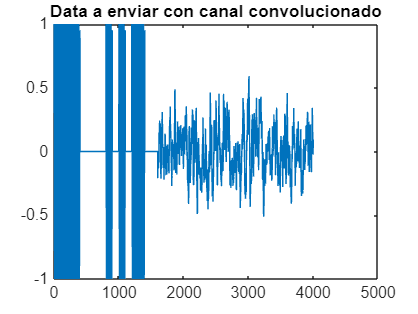

write_float_binary(modulatedSignalTx,'envioOOKyDATA.bin');

read = read_float_binary('envioOOKyDATA.bin')';

figure
plot(read(1:4001))
title("Data a enviar con canal convolucionado")

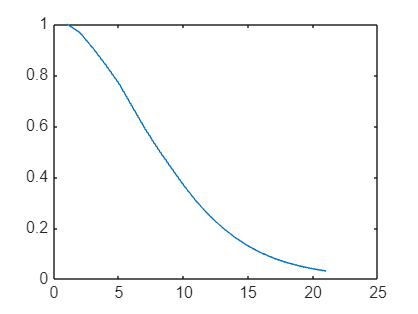

figure
plot(autocorr(read))

% Modular los bits con la portadora

write_float_binary(shapedSignal,'dataOG.bin');

% read7 = read_float_binary('originalsignalnoH.bin')';
% 
% figure
% plot(read7)
% title("Data original sin canal convolucionado")

% write_float_binary(tx_signal,'enviotestingimpulso.bin');
% 
% read = read_float_binary('enviotestingimpulso.bin')';
% 
% figure
% plot(read)


% read2 = read_float_binary('SENT.bin')';
% 
% figure
% plot(read2(1:10000))
% title("Data a enviar modulada por cos(t)")


function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

function bits = demodulate_signal(signal, samples_per_bit)
    % Inicializar vector de bits
    num_bits = length(signal) / samples_per_bit;
    bits = zeros(1, num_bits);

    % Determinar el valor de cada bit
    for i = 1:num_bits
        segment = signal((i-1)*samples_per_bit + 1 : i*samples_per_bit);
        if mean(segment) > 0
            bits(i) = 1;
        else
            bits(i) = 0;
        end
    end
end


function ber = calculate_ber(bits_received, bits_original)
    % Verificar que los arreglos tengan la misma longitud
    if length(bits_received) ~= length(bits_original)
        error('Los arreglos de bits deben tener la misma longitud');
    end
    
    % Calcular el número de errores
    num_errors = sum(bits_received ~= bits_original);
    
    % Calcular el BER
    ber = num_errors / length(bits_original);
end